
$$\theta'' + \sin \theta = 0, 
\qquad \theta(0)=0,\quad\theta'(0)=q$$


## Phase plane

Our justification for using the linear approximation, $\theta''+\theta=0$, is that there is not much difference if $|\theta|$ remains small.

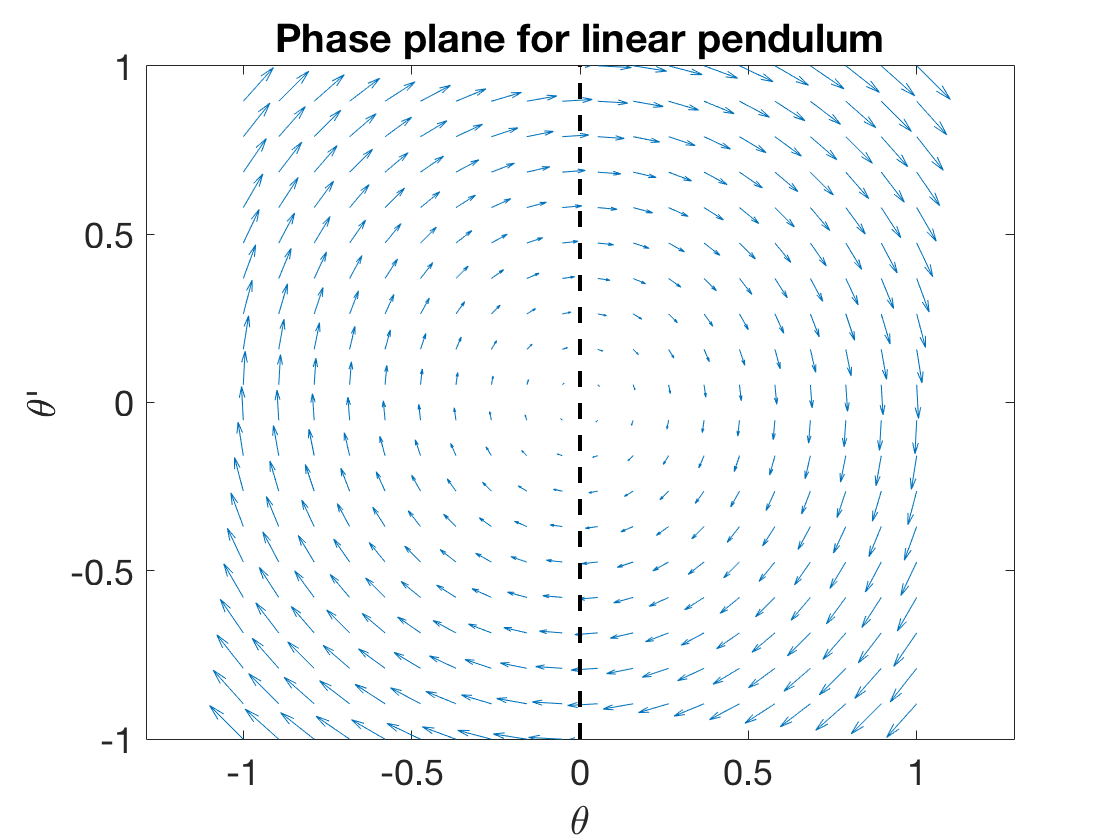

clf
L = chebop( @(u) diff(u,2)+u, [0,30]);
quiver(L,[-1 1 -1 1])
hold on, plot([0 0],[-1 1],'k--')
xlabel("\theta"), ylabel("\theta'"), axis equal
title('Phase plane for linear pendulum')

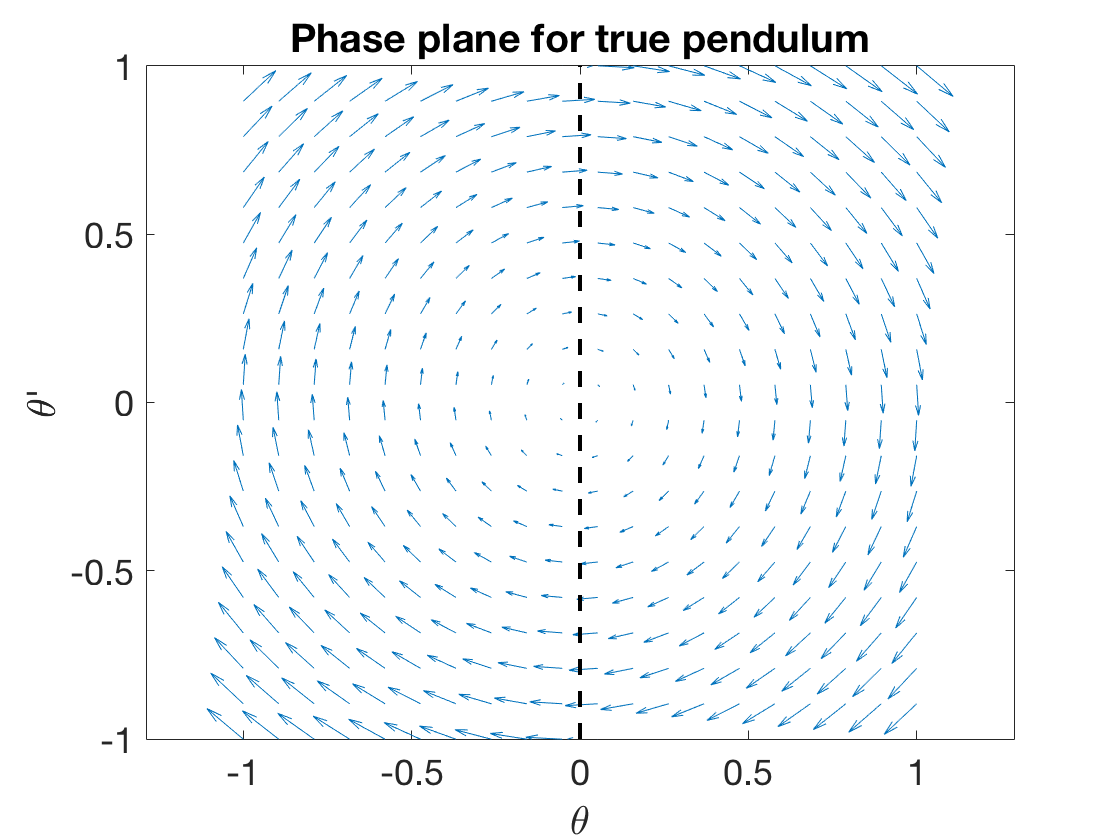

N = chebop( @(u) diff(u,2)+sin(u), [0,30]);
clf, quiver(N,[-1 1 -1 1])
hold on, plot([0 0],[-1 1],'k--')
xlabel("\theta"), ylabel("\theta'"), axis equal
title('Phase plane for true pendulum')

 When we zoom out, we see that the global structures of the problems are completely different.

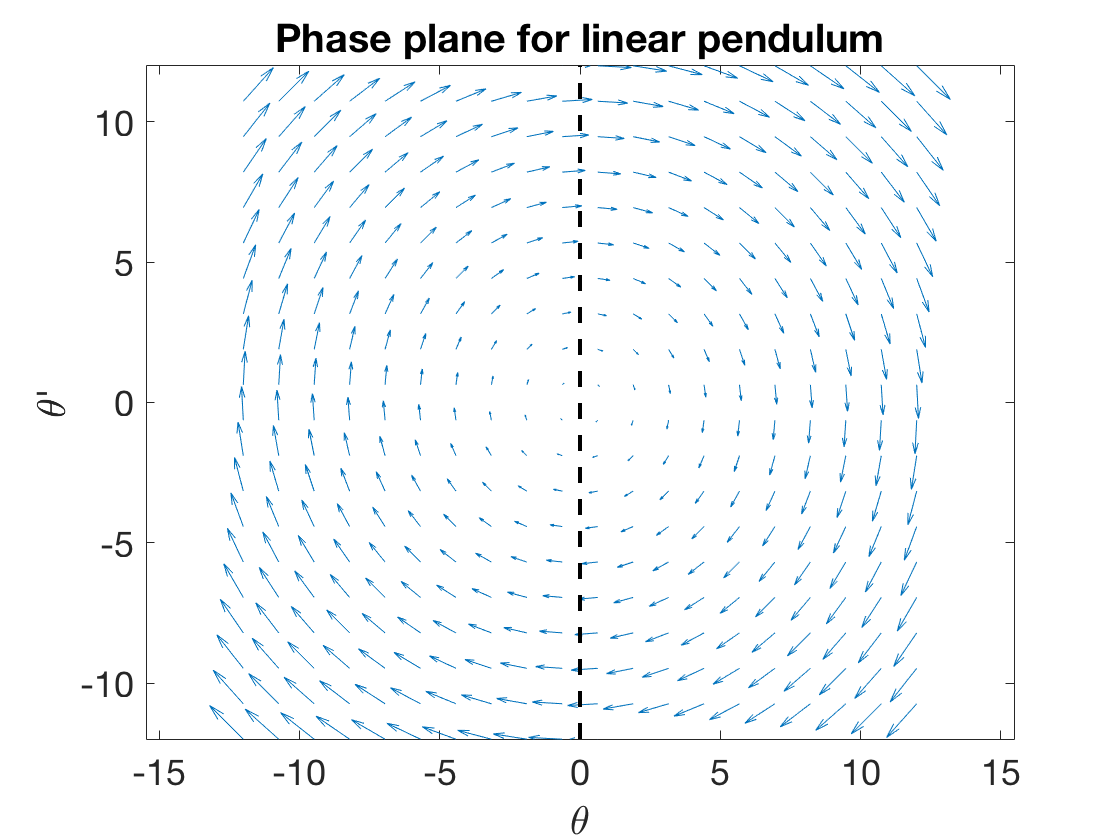

L = chebop( @(u) diff(u,2)+u, [0,30]);
clf, quiver(L,12*[-1 1 -1 1])
hold on, plot([0 0],[-12 12],'k--')
xlabel("\theta"), ylabel("\theta'"), axis equal
title('Phase plane for linear pendulum')

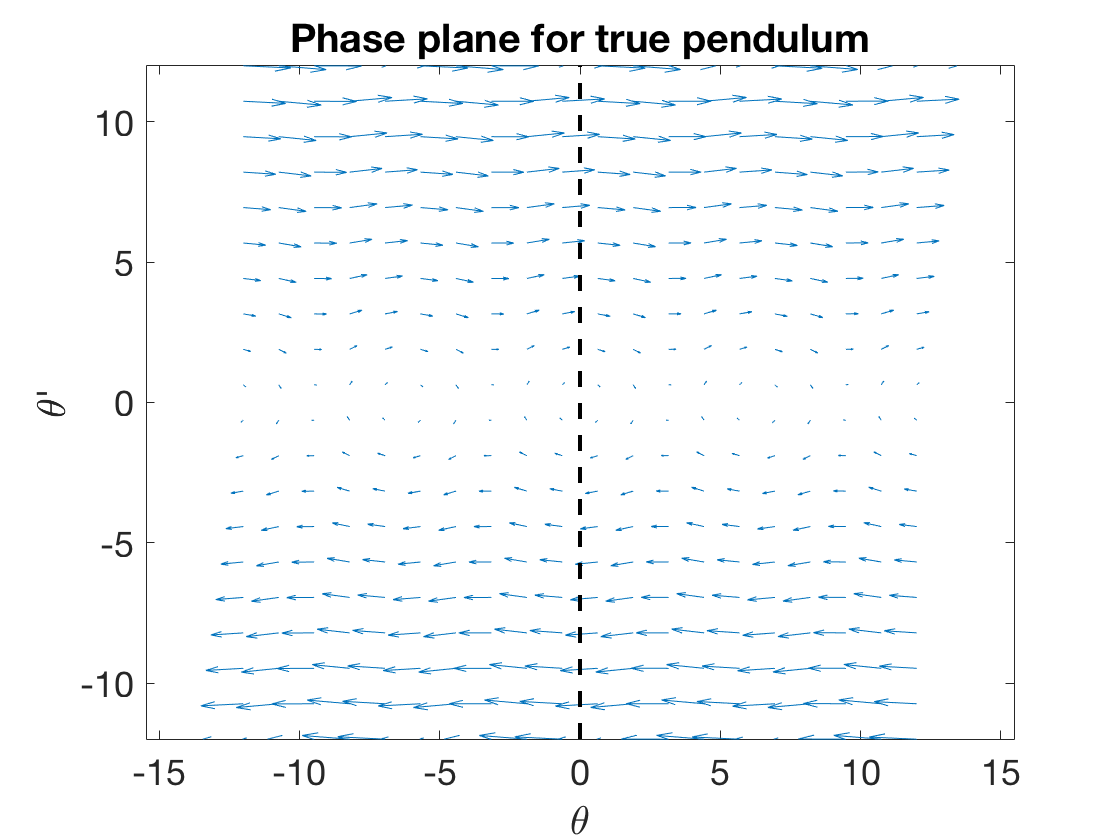


N = chebop( @(u) diff(u,2)+sin(u), [0,30]);
clf,quiver(N,12*[-1 1 -1 1])
hold on, plot([0 0],[-12 12],'k--')
xlabel("\theta"), ylabel("\theta'"), axis equal
title('Phase plane for true pendulum')

## Solutions 

We also need to be a little careful. Even small differences become large over enough time, because the two versions of the solution go out of phase. 

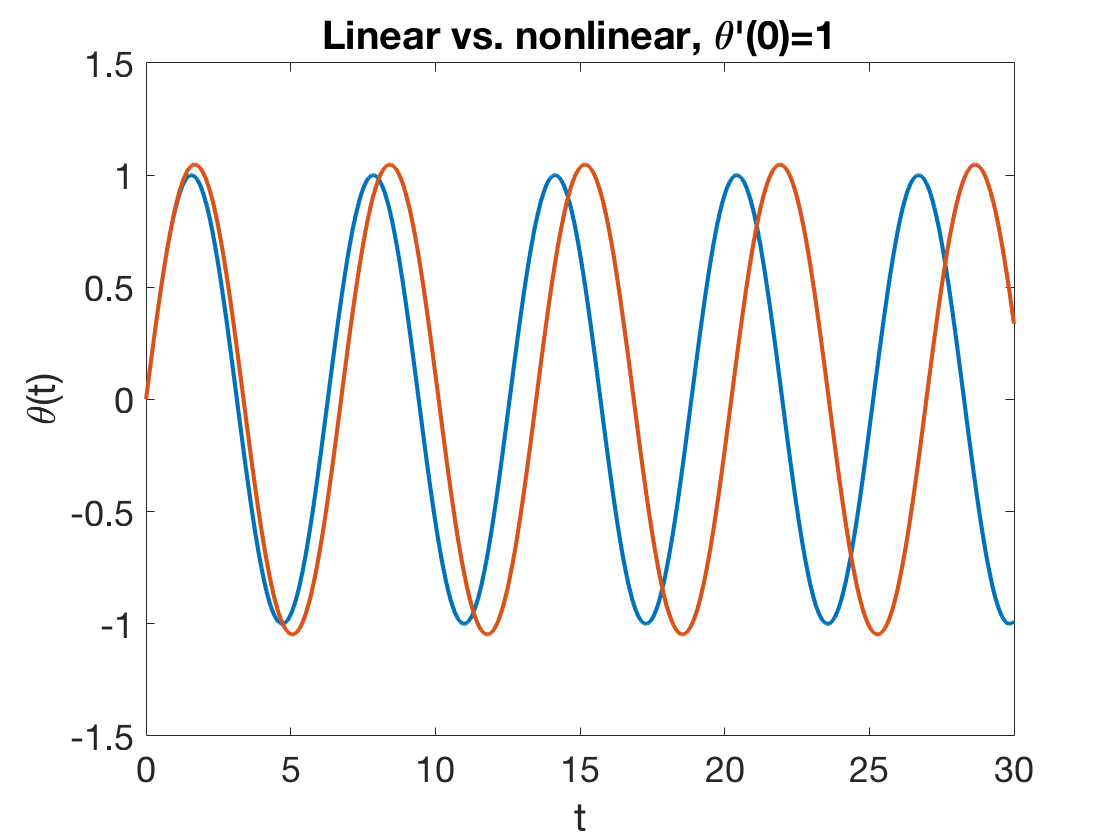

L.lbc = [0,1];  N.lbc = [0,1];
clf, plot([L\0,N\0])
xlabel('t'), ylabel('\theta(t)')
title("Linear vs. nonlinear, \theta'(0)=1")

We observe that in the nonlinear case, both the amplitude and period are larger. (This is easily explained in terms of having a weaker restoring torque than the linear model claims.)

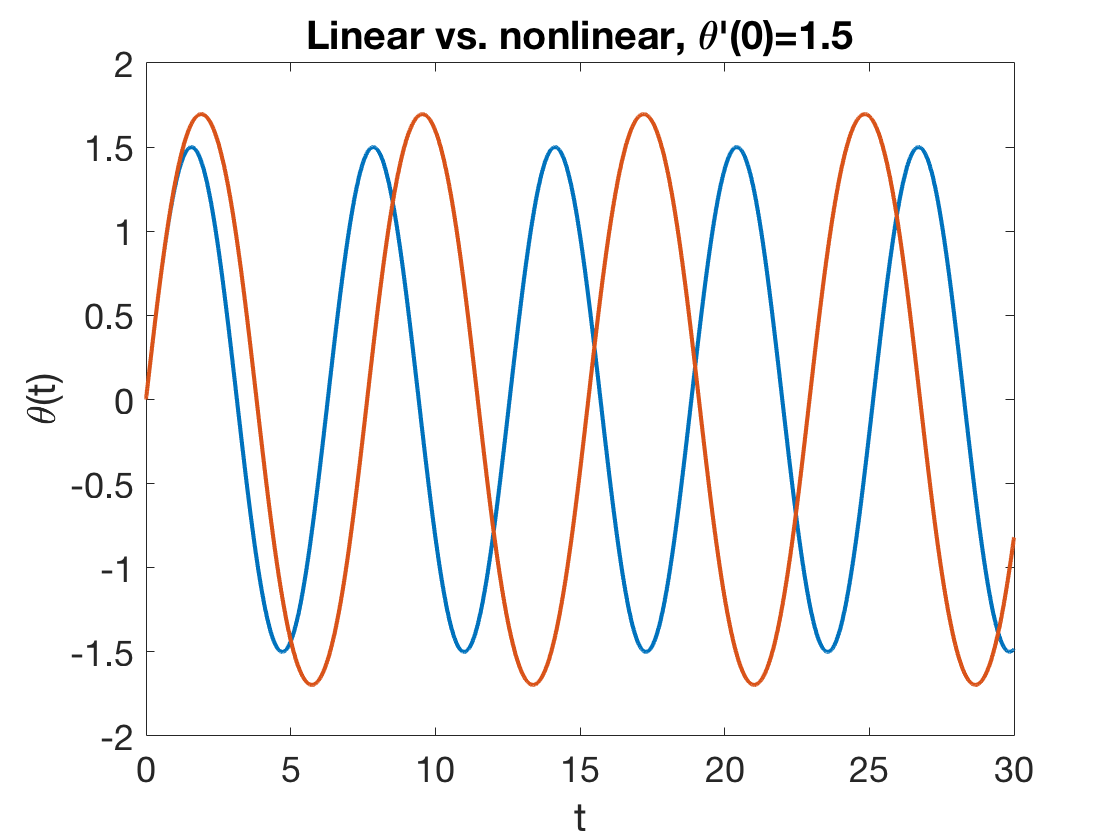

L.lbc = [0,1.5];  N.lbc = [0,1.5];
plot([L\0,N\0])
xlabel('t'), ylabel('\theta(t)')
title("Linear vs. nonlinear, \theta'(0)=1.5") 

And for some initial data, the solutions are entirely different!

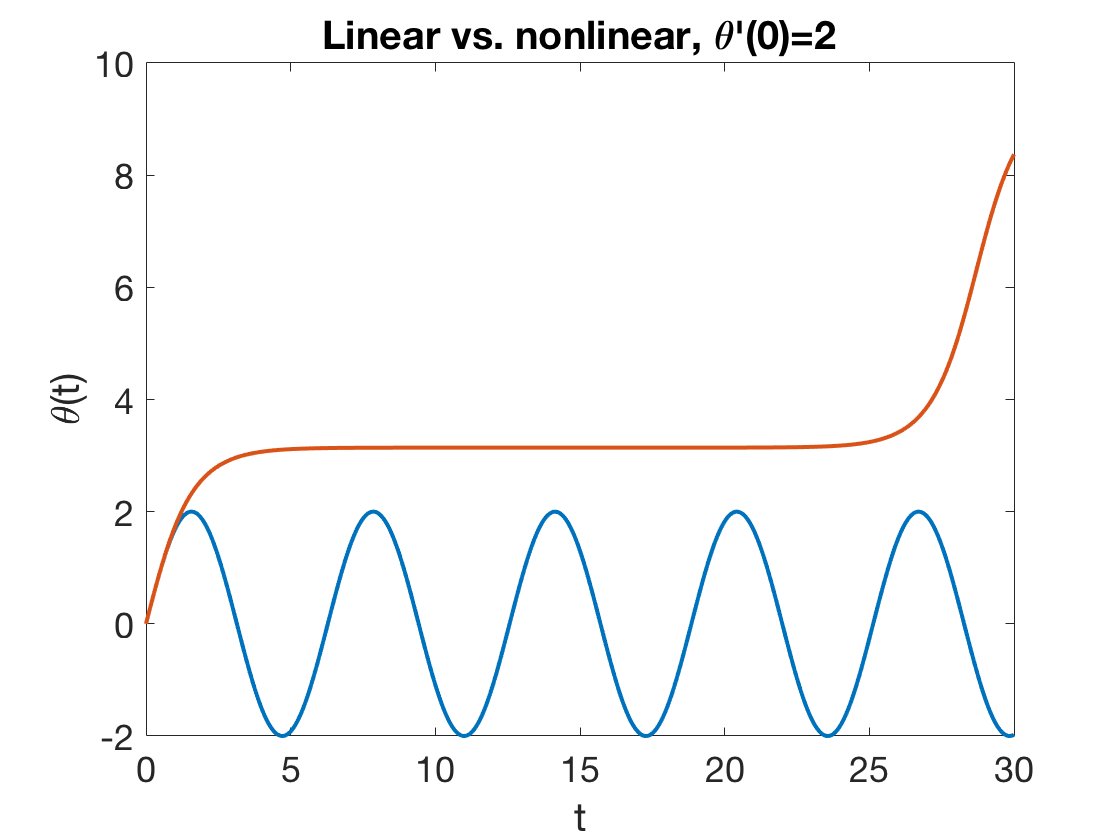

L.lbc = [0,2];  N.lbc = [0,2];
plot([L\0,N\0])
xlabel('t'), ylabel('\theta(t)')
title("Linear vs. nonlinear, \theta'(0)=2")

## Period

Finding the period is simply a matter of finding the differences between successive local maxima. 

N.lbc = [0;0.5];  u = N\0;
[~,t] = max(u,'local')

t =     1.5962
    7.9812
   14.3662
   20.7511
   27.1361


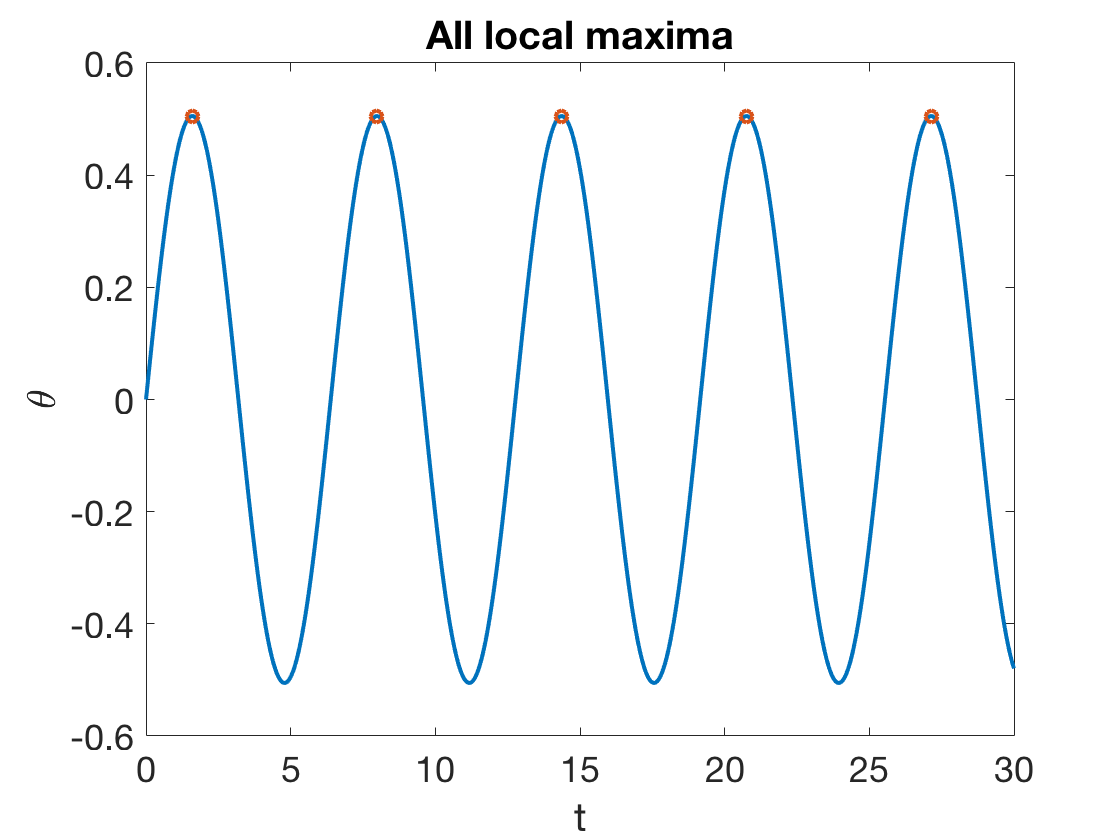

clf, plot(u)
hold on, plot(t,u(t),'o')
xlabel t, ylabel \theta
title('All local maxima')

period = diff(t)

period =     6.3850
    6.3850
    6.3850
    6.3850


We observe that unlike the linear case, the period depends on the amplitude (here in the form of the initial velocity). 

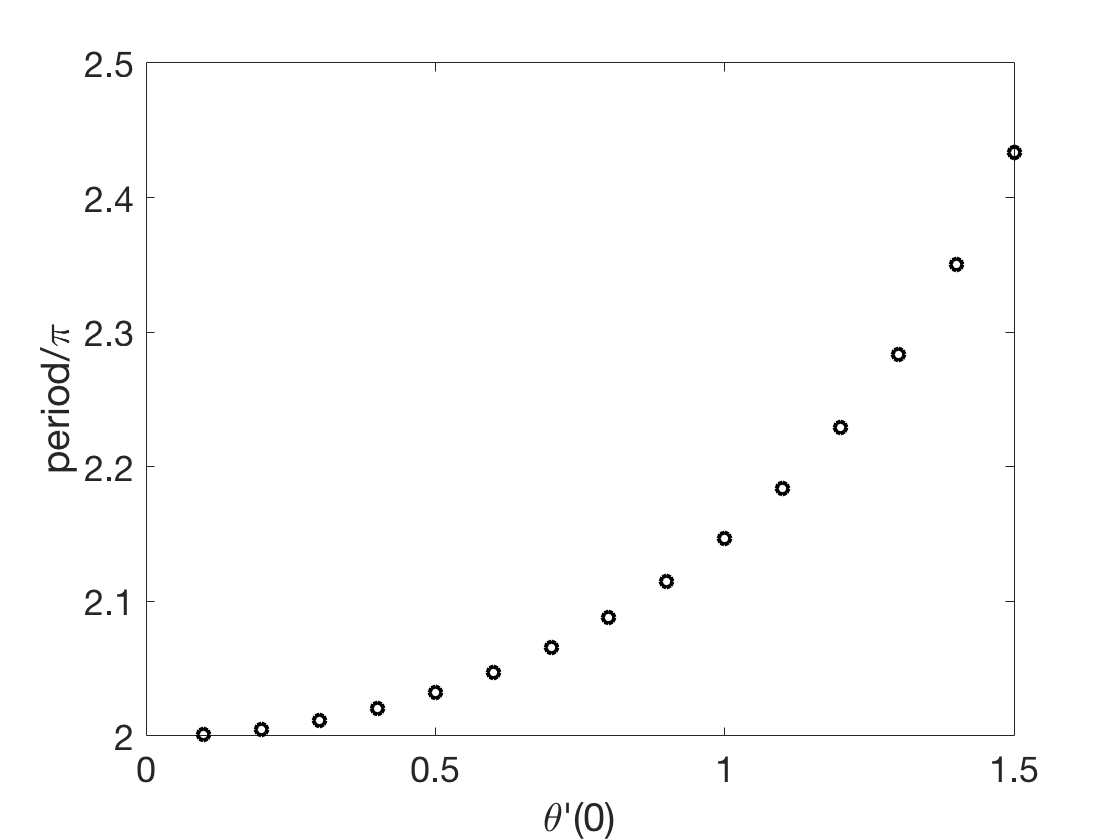

clf
for up = 0.1:0.1:1.5
    N.lbc = [0;up];  u = N\0;
    [~,t] = max(u,'local');
    plot(up,(t(3)-t(2))/pi,'ko'), hold on    
end
xlabel("\theta'(0)"), ylabel('period/\pi')

## Boundary-value problem

At some initial condition in the above, the period of motion is exactly 7 (about $2.23\pi$). 

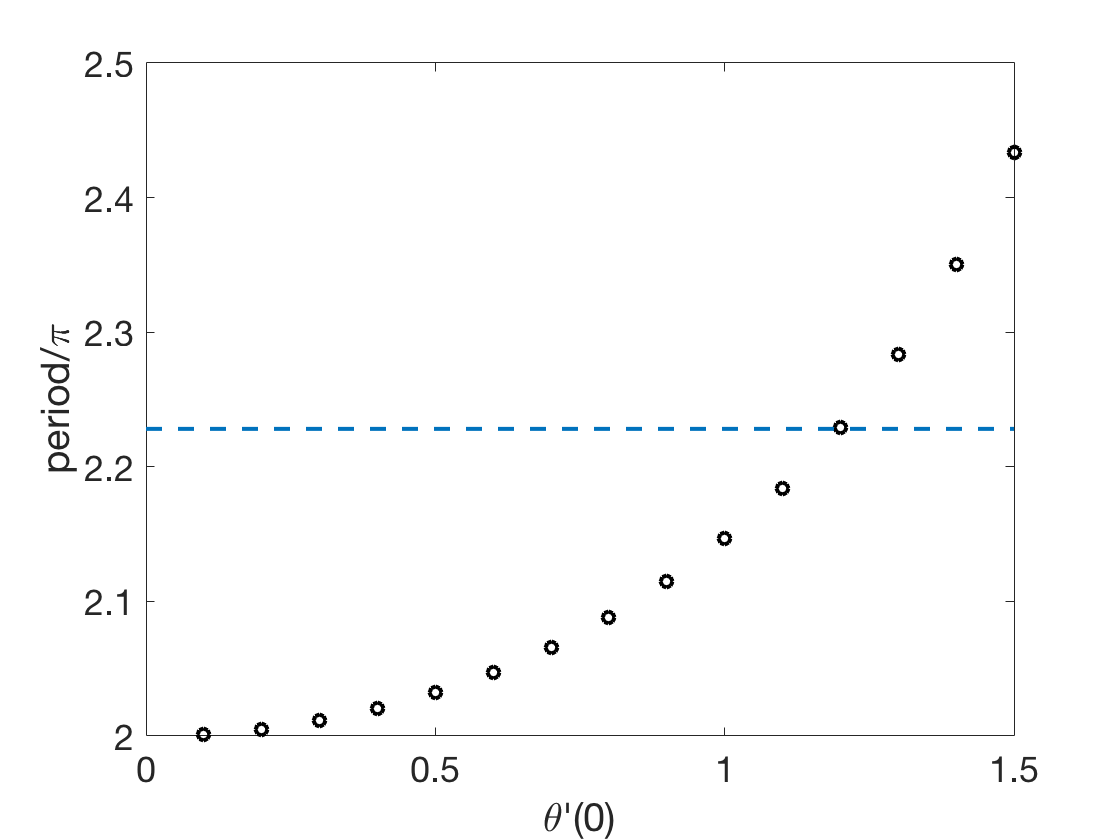

hold on, plot([0 1.5],[7 7]/pi,'--')

We could do a simple bisection search for this solution. (I.e., shooting.)

N.lbc = [0;1];  ulo = N\0;
[~,t] = max(ulo,'local');  t(2)-t(1)

ans = 6.7430

N.lbc = [0;1.3];  uhi = N\0;
[~,t] = max(uhi,'local');  t(2)-t(1)

ans = 7.1738

N.lbc = [0;1.15];  umid = N\0;
[~,t] = max(umid,'local');  t(2)-t(1)

ans = 6.9290

But we could instead acknowledge that this is a different kind of problem. We no longer give a constraint on the initial velocity, but rather on the position at two different times. 


$$\theta''+\sin \theta=0, \qquad \theta(0)=0, \quad \mathbf{\theta(7)=0}$$


Here is one rather boring solution of this problem.

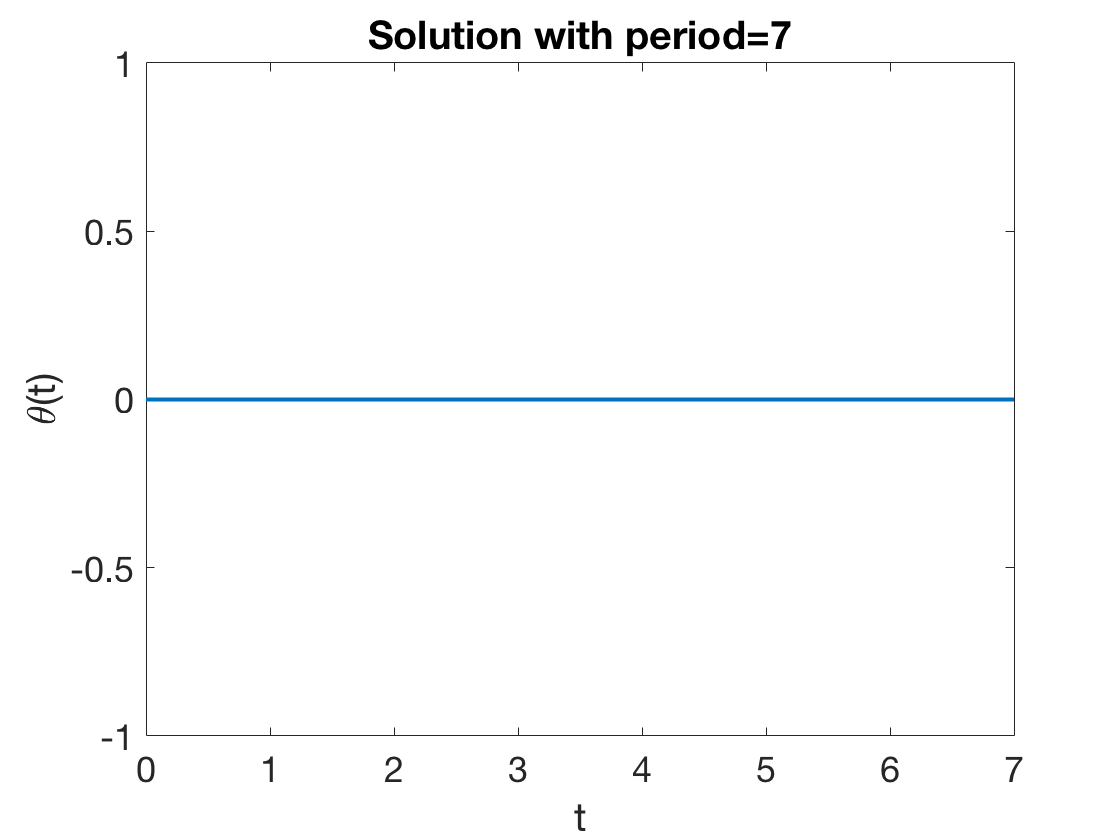

N.domain = [0,7];
N.lbc = 0;  N.rbc = 0;
clf, plot(N\0)
xlabel('t'), ylabel('\theta(t)')
title('Solution with period=7')

But from the shooting instance above, we fully expect that there is another solution of this problem. If we give the solver a hint about what the solution looks like (one of our near-misses), it finds the desired solution exactly. 

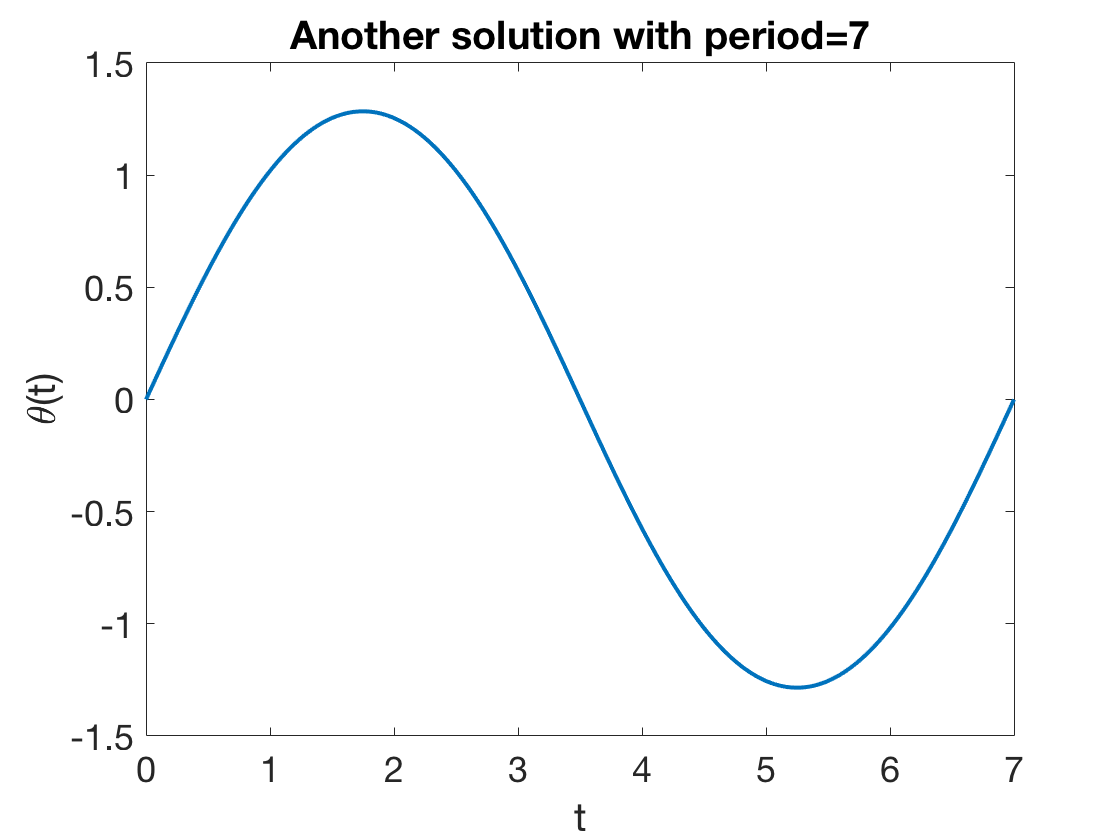

N.init = ulo{0,7};
plot(N\0)
xlabel('t'), ylabel('\theta(t)')
title('Another solution with period=7')

In fact, though, it's reasonable to expect at least one more solution, where the period of motion is 14. Another hint gets us this one too.

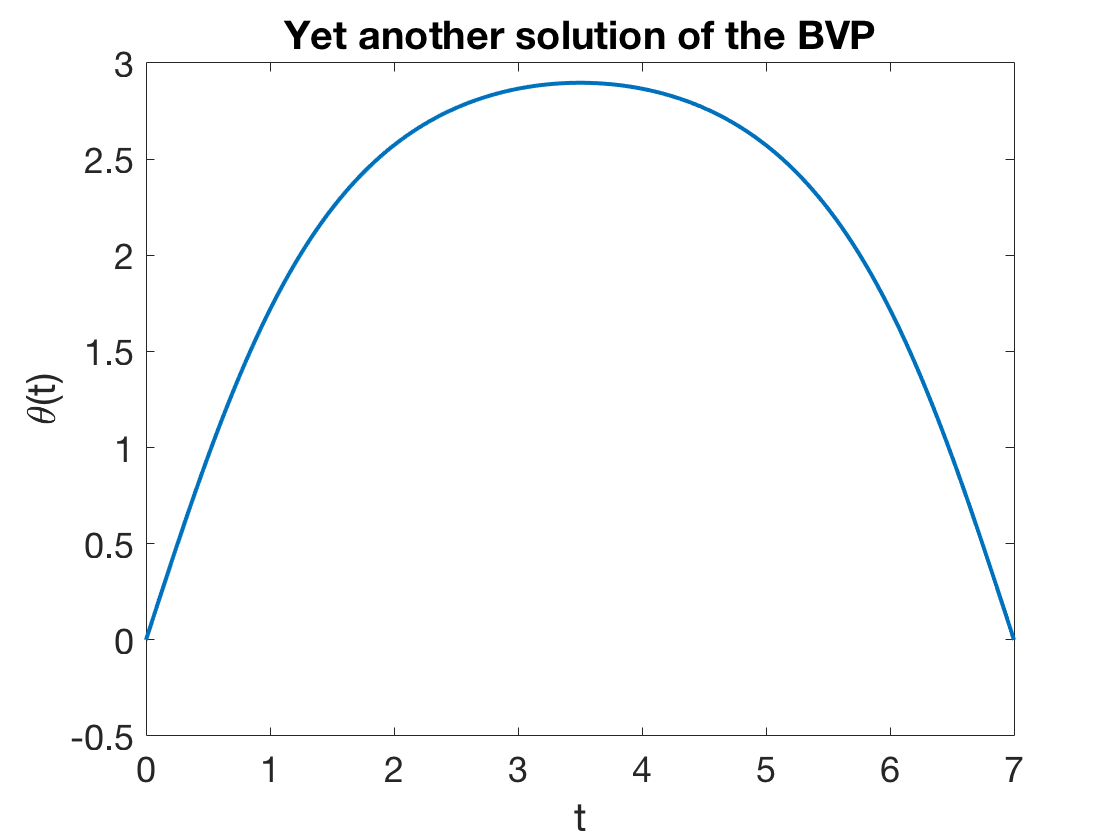

N.init = chebfun('3*sin(pi*t/7)',[0 7]);
plot(N\0)
xlabel('t'), ylabel('\theta(t)')
title('Yet another solution of the BVP')

Are there more solutions?